## statistical distribution of outputs with stationary inputs

tot_len = 10;
gi_val = zeros(1,tot_len); gi_val_cond = zeros(1,tot_len);
CN = zeros(1,tot_len); CG = zeros(1,tot_len); CG_cond = zeros(1,tot_len);
VAx = zeros(1,tot_len); Ls = zeros(1, tot_len);

rowNb = 50; colNb = 10; depNb = 100;
Pc = [0.865 0.865]; NPc = [0.89 0.89]; Pe_rad = [0.5 0.5]; Pe_tan = [0.05 0.05];
radDist = ones(1, colNb); Lce = 2.81e-3;
Dc = 34.23e-6; Dc_cv = 0.24;
Dp = 8.0e-9; Dm = 5.8e-6; A = 27; B = 3.1;
fc = 0.41; fpf = 0.78;
fap = 0.055;
e_mean = 0.015;
e_cv = 0.35;
Tm = 234e-9;
Lp = 654e-9;
ASPcalcmethod = 'Pore';

jt = 5; stepSize = 0.3; %MPa
itmax = 20;  inEmb = 1;
AvgBool = false;

Kmax = zeros(1,tot_len); PLC = zeros(itmax,tot_len); PV = zeros(itmax,tot_len);
Pressures = zeros(itmax,tot_len); ktot = zeros(1,tot_len); ktot_xa = zeros(1,tot_len);
Lv = zeros(1,tot_len); lumFrac = zeros(1,tot_len);
% parfor i = 1 : tot_len
parfor i = 1 : tot_len
    disp(strcat('iteration: ',num2str(i)))
    An = XylemNet(rowNb,colNb,depNb,Pc,NPc,Pe_rad,Pe_tan,radDist, Lce,Dc,Dc_cv,Dp,Dm,A,B,fc,fpf,fap,...
        e_mean,e_cv,Tm,Lp,ASPcalcmethod);
    % conncomp(An.gCav);
    Ls(i) = mean([An.Conduits.Length]);
    [gi_val(i), gi_val_cond(i), CN(i), CG(i), CG_cond(i), VAx(i)] = gi(An);
    if any([An.Conduits.Length] == rowNb*Lce)
        disp('There exists open vessels.')
    end
    Lv(i) = mean([An.Conduits.Length]);
    lumFrac(i) = VAx(i) .* pi / 4 .* mean([An.Conduits.Diameter].^2) .* 1e6;
    [PLCvar,PVvar,Pressuresvar,Kmaxvar,~,~,~,...
        ~,~,~] = cavitation_process(An,jt,stepSize,itmax,inEmb,...
        AvgBool);

    PLC(:,i) = PLCvar';PV(:,i) = PVvar';Pressures(:,i) = Pressuresvar';
    Kmax(i) = Kmaxvar(1);

    [~,~,~,ktot(i),ktot_xa(i),~] =...
        compute_hydraulics(An.gCond,1e6,0,...
        {An.Dcross(1,:), An.Dcross(2,:), An.Dcross(3,:), An.Dcross(4,:)},...
        VAx(i));

end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
iteration:1
iteration:2
iteration:3
iteration:4
iteration:6
iteration:5
iteration:8
iteration:10
iteration:7
iteration:9


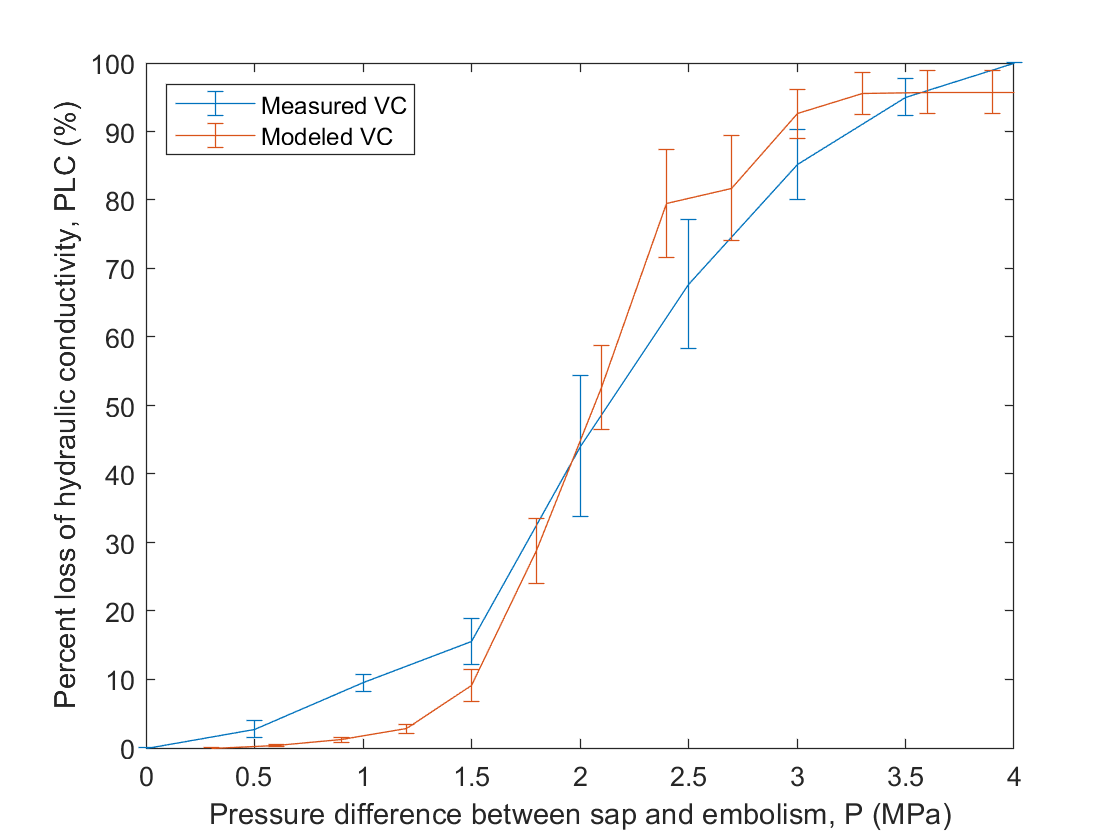


PLCmean = mean(PLC,2);
PLCse = std(PLC,0,2) / sqrt(size(PLC,2));

AnVC = readtable('..\Acer VCs.xlsx', 'Sheet',2, 'PreserveVariableNames', true);
figure;
errorbar(-AnVC.P,AnVC.mean,AnVC.se)
hold on
errorbar(Pressures(:,1), PLCmean, PLCse)
xlim([0 4])
xlabel('Pressure difference between sap and embolism, P (MPa)')
ylabel('Percent loss of hydraulic conductivity, PLC (%)')
legend('Measured VC', 'Modeled VC', 'Location', 'northwest')


disp(strcat('k_(xa,mean) = ', num2str(mean(ktot_xa)), ' m^2/(MPa.s) or ',...
    num2str(mean(ktot_xa)*1e6/1e3), ' mg/(kPa.s.mm)'))

k_(xa,mean) =0.0022289 m^2/(MPa.s) or2.2289 mg/(kPa.s.mm)


disp(strcat('k_(xa,std) = ', num2str(std(ktot_xa)), ' m^2/(MPa.s) or ',...
    num2str(std(ktot_xa)*1e6/1e3), ' mg/(kPa.s.mm)'))

k_(xa,std) =0.00066809 m^2/(MPa.s) or0.66809 mg/(kPa.s.mm)



disp(strcat('VAx_mean = ', num2str(mean(VAx)), ' VAx_std = ',...
    num2str(std(VAx))))

VAx_mean =263.8371 VAx_std =12.5745


disp(strcat('GI_mean = ', num2str(mean(gi_val_cond)), ' GI_std = ',...
    num2str(std(gi_val))))

GI_mean =1.9797 GI_std =0.13412


disp(strcat('L_v = ', num2str(mean(Lv)), ' L_{v,std} = ',...
    num2str(std(Lv))))

L_v =0.027823 L_{v,std} =0.00057868


disp(strcat('F = ', num2str(mean(lumFrac)), ' L_{v,std} = ',...
    num2str(std(lumFrac))))

F =0.25559 L_{v,std} =0.01051



% save('Vessel connectivity/stationary.mat','PLC', 'PV', 'Pressures',...
%     'ktot_xa', 'ktot', 'gi_val', 'CN', 'CG', 'VAx', 'PV', 'Kmax')

## Vary vessel length

% Pc_mc = repelem(0.7:0.005:0.8,10);
%
% gi_val = zeros(1,length(Pc_mc)); CN = zeros(1,length(Pc_mc));
% CG = zeros(1,length(Pc_mc)); VAx = zeros(1,length(Pc_mc));
% openVessel = false(1,length(Pc_mc)); Ls = zeros(1,length(Pc_mc));
% simulationNotCompleted = false(1,length(Pc_mc));
% deg_avg = zeros(1,length(Pc_mc)); deg_2_avg = zeros(1,length(Pc_mc));
% deg_max = zeros(1,length(Pc_mc));
%
% rowNb = 50; colNb = 10; depNb = 150;
% NPc = [0.86 0.86]; Pe_rad = [0.8 0.8]; Pe_tan = [0.05 0.05];
% % Average vessel length is given by 1 + Pc / (1 - Pc). 0.86 -> 7.14. A
% % rowNb of 50 is enough
% radDist = ones(1, colNb); Lce = 2.88e-3;
% % Dc = 24.6e-6; Dc_cv = 0.00012;
% Dc = 21.8e-6; Dc_cv = 0.33;
% % formula for ASP: obj.ASP = wblrnd(obj.A/obj.Npit^(1/obj.B),obj.B);
% Dp = 16.0e-9; Dm = 6.3e-6; A = 21; B = 3.1;
% fc = 0.31; fpf = 0.7;
% fap = 0.06;
% e_mean = 0.015;
% e_cv = 0.35;
% Tm = 234e-9;
% Lp = 654e-9;
% ASPcalcmethod = 'Pore';
%
% jt = 10; stepSize = 0.3; %MPa
% itmax = 15;  inEmb = 1;
% AvgBool = false;
%
% Kmax = zeros(1,length(Pc_mc)); PLC = zeros(15,length(Pc_mc));
% PV = zeros(15,length(Pc_mc));  Pressures = zeros(15,length(Pc_mc));
% ktot = zeros(1,length(Pc_mc)); ktot_xa = zeros(1,length(Pc_mc));
%
% for i = 1 : length(Pc_mc)
%     disp(strcat('iteration: ',num2str(i)))
%     try
%         Agg = XylemNet(rowNb,colNb,depNb,[Pc_mc(i) Pc_mc(i)],NPc,Pe_rad,Pe_tan,radDist,...
%             Lce,Dc,Dc_cv,Dp,Dm,A,B,fc,fpf,fap,...
%             e_mean,e_cv,Tm,Lp,ASPcalcmethod);
%         % conncomp(Agg.gCav);
%         [gi_val(i), CN(i), CG(i), VAx(i)] = gi(Agg);
%         if any([Agg.Conduits.Length] == rowNb*Lce)
%             disp('There exists open vessels.')
%             openVessel(i) = true;
%         end
%         Ls(i) = mean([Agg.Conduits.Length]);
%         deg_avg(i) = mean([Agg.Conduits.NConConduits]);
%         deg_2_avg(i) = mean([Agg.Conduits.NConConduits].^2);
%         deg_max(i) = max([Agg.Conduits.NConConduits]);
%
%         [PLCvar,PVvar,Pressuresvar,Kmaxvar,~,~,~,...
%             ~,~,~] = cavitation_process(Agg,jt,stepSize,itmax,inEmb,...
%             AvgBool);
%
%         PLC(:,i) = PLCvar';PV(:,i) = PVvar';Pressures(:,i) = Pressuresvar';
%         Kmax(i) = Kmaxvar(1);
%
%         [~,~,~,ktot(i),ktot_xa(i),~] =...
%             compute_hydraulics(Agg.gCond,1e6,0,...
%             {Agg.Dcross(1,:), Agg.Dcross(2,:), Agg.Dcross(3,:), Agg.Dcross(4,:)},...
%             VAx(i));
%     catch
%         disp(strcat('iteration',num2str(i),' had an error'))
%         simulationNotCompleted(i) = true;
%     end
%
% end
%
% save('Vessel connectivity/length variation.mat','PLC', 'PV', 'Pressures',...
%     'ktot_xa', 'ktot', 'gi_val', 'CN', 'CG', 'VAx', 'PV', 'Kmax', 'openVessel',...
%     'Ls')

## Vary vessel density

% NPc_mc = repelem(0.83:0.005:0.89,10);
%
% gi_val = zeros(1,length(NPc_mc)); CN = zeros(1,length(NPc_mc));
% CG = zeros(1,length(NPc_mc)); VAx = zeros(1,length(NPc_mc));
% openVessel = false(1,length(NPc_mc)); Ls = zeros(1,length(NPc_mc));
% simulationNotCompleted = false(1,length(NPc_mc));
% deg_avg = zeros(1,length(NPc_mc)); deg_2_avg = zeros(1,length(NPc_mc));
% deg_max = zeros(1,length(NPc_mc));
%
% rowNb = 50; colNb = 10; depNb = 150;
% Pc = [0.765 0.765]; Pe_rad = [0.8 0.8]; Pe_tan = [0.05 0.05];
% % Average vessel length is given by 1 + Pc / (1 - Pc). 0.86 -> 7.14. A
% % rowNb of 50 is enough
% radDist = ones(1, colNb); Lce = 2.88e-3;
% % Dc = 24.6e-6; Dc_cv = 0.00012;
% Dc = 21.8e-6; Dc_cv = 0.33;
% % formula for ASP: obj.ASP = wblrnd(obj.A/obj.Npit^(1/obj.B),obj.B);
% Dp = 16.0e-9; Dm = 6.3e-6; A = 21; B = 3.1;
% fc = 0.31; fpf = 0.7;
% fap = 0.06;
% e_mean = 0.015;
% e_cv = 0.35;
% Tm = 234e-9;
% Lp = 654e-9;
% ASPcalcmethod = 'Pore';
%
% jt = 10; stepSize = 0.3; %MPa
% itmax = 15;  inEmb = 1;
% AvgBool = false;
%
% Kmax = zeros(1,length(NPc_mc)); PLC = zeros(15,length(NPc_mc));
% PV = zeros(15,length(NPc_mc));  Pressures = zeros(15,length(NPc_mc));
% ktot = zeros(1,length(NPc_mc)); ktot_xa = zeros(1,length(NPc_mc));
%
% parfor i = 1 : length(NPc_mc)
%     disp(strcat('iteration: ',num2str(i)))
%     try
%         Agg = XylemNet(rowNb,colNb,depNb,Pc,[NPc_mc(i) NPc_mc(i)],Pe_rad,Pe_tan,radDist,...
%             Lce,Dc,Dc_cv,Dp,Dm,A,B,fc,fpf,fap,...
%             e_mean,e_cv,Tm,Lp,ASPcalcmethod);
%         % conncomp(Agg.gCav);
%         [gi_val(i), CN(i), CG(i), VAx(i)] = gi(Agg);
%         if any([Agg.Conduits.Length] == rowNb*Lce)
%             disp('There exists open vessels.')
%             openVessel(i) = true;
%         end
%         Ls(i) = mean([Agg.Conduits.Length]);
%         deg_avg(i) = mean([Agg.Conduits.NConConduits]);
%         deg_2_avg(i) = mean([Agg.Conduits.NConConduits].^2);
%         deg_max(i) = max([Agg.Conduits.NConConduits]);
%
%         [PLCvar,PVvar,Pressuresvar,Kmaxvar,~,~,~,...
%             ~,~,~] = cavitation_process(Agg,jt,stepSize,itmax,inEmb,...
%             AvgBool);
%
%         PLC(:,i) = PLCvar';PV(:,i) = PVvar';Pressures(:,i) = Pressuresvar';
%         Kmax(i) = Kmaxvar(1);
%
%         [~,~,~,ktot(i),ktot_xa(i),~] =...
%             compute_hydraulics(Agg.gCond,1e6,0,...
%             {Agg.Dcross(1,:), Agg.Dcross(2,:), Agg.Dcross(3,:), Agg.Dcross(4,:)},...
%             VAx(i));
%     catch
%         disp(strcat('iteration',num2str(i),' had an error'))
%         simulationNotCompleted(i) = true;
%     end
%
% end
%
% save('Vessel connectivity/vessel density variation.mat','PLC', 'PV', 'Pressures',...
%     'ktot_xa', 'ktot', 'gi_val', 'CN', 'CG', 'VAx', 'PV', 'Kmax', 'openVessel',...
%     'Ls')

## Vary both density and length

% Pc_mc = repelem(0.8:0.02:0.9,5);
% NPc_mc = repelem(0.89:0.01:0.94,5);
%
% tot_len = length(Pc_mc) * length(NPc_mc);
% gi_val = zeros(1,tot_len); CN = zeros(1,tot_len);
% CG = zeros(1,tot_len); VAx = zeros(1,tot_len);
% openVessel = false(1,tot_len); Ls = zeros(1,tot_len);
% Dcs = zeros(1, tot_len);
% simulationNotCompleted = false(1,tot_len);
% deg_avg = zeros(1,tot_len); deg_2_avg = zeros(1,tot_len);
% deg_max = zeros(1,tot_len); Ac_fp_avg = zeros(1, tot_len);
% lumFrac = zeros(1,tot_len);
%
% rowNb = 50; colNb = 10; depNb = 100;
% Pc = [0.85 0.85]; NPc = [0.924 0.924]; Pe_rad = [0.7 0.7]; Pe_tan = [0.15 0.15];
% radDist = ones(1, colNb); Lce = 2.81e-3;
% Dc = 25.99e-6; Dc_cv = 0.09;
% Dp = 8.8e-9; Dm = 6.9e-6; A = 700; B = 1.2;
% fc = 0.38; fpf = 0.71;
% fap = 0.055;
% e_mean = 0.015;
% e_cv = 0.35;
% Tm = 234e-9;
% Lp = 654e-9;
% ASPcalcmethod = 'Pore';
%
% jt = 5; stepSize = 0.3; %MPa
% itmax = 20;  inEmb = 1;
% AvgBool = false;
%
% Kmax = zeros(1,tot_len); PLC = zeros(itmax,tot_len);
% PV = zeros(itmax,tot_len);  Pressures = zeros(itmax,tot_len);
% ktot = zeros(1,tot_len); ktot_xa = zeros(1,tot_len);
% voltot = zeros(1,tot_len);
% embNb = zeros(itmax,tot_len); ncNb = zeros(itmax,tot_len);
%
% %Split params into cell arrays
% params = cell(1,tot_len);
% for i = 1 : tot_len
%     [I1, I2] = ind2sub([length(Pc_mc) length(NPc_mc)], i);
%     params{i} = [Pc_mc(I1) NPc_mc(I2)];
% end
%
% parfor i = 1 : tot_len
%
%     disp(strcat('iteration: ',num2str(i),' of', num2str(tot_len)))
%     try
%         As = XylemNet(rowNb,colNb,depNb,[params{i}(1) params{i}(1)],...
%             [params{i}(2) params{i}(2)],Pe_rad,Pe_tan,radDist,...
%             Lce,Dc,Dc_cv,Dp,Dm,A,B,fc,fpf,fap,...
%             e_mean,e_cv,Tm,Lp,ASPcalcmethod);
%         % conncomp(Agg.gCav);
%         [~, gi_val(i), CN(i), ~, CG(i), VAx(i)] = gi(As);
%         lumFrac(i) = VAx(i) .* pi / 4 .* mean([As.Conduits.Diameter].^2) .* 1e6;
%         if any([As.Conduits.Length] == rowNb*Lce)
%             disp('There exists open vessels.')
%             openVessel(i) = true;
%         end
%         Ls(i) = mean([As.Conduits.Length]);
%         Dcs(i) = mean([As.Conduits.Diameter]);
%         deg_avg(i) = mean([As.Conduits.NConConduits]);
%         deg_2_avg(i) = mean([As.Conduits.NConConduits].^2);
%         deg_max(i) = max([As.Conduits.NConConduits]);
%
%         [PLCvar,PVvar,Pressuresvar,Kmaxvar,~,voltotvar,embNbvar,ncNbvar,...
%             ~,~] = cavitation_process(As,jt,stepSize,itmax,inEmb,...
%             AvgBool);
%
%         PLC(:,i) = PLCvar';PV(:,i) = PVvar';Pressures(:,i) = Pressuresvar';
%         Kmax(i) = Kmaxvar(1); voltot(i) = voltotvar;
%         embNb(:,i) = embNbvar'; ncNb(:,i) = ncNbvar';
%
%         [~,~,~,ktot(i),ktot_xa(i),~] =...
%             compute_hydraulics(As.gCond,1e6,0,...
%             {As.Dcross(1,:), As.Dcross(2,:), As.Dcross(3,:), As.Dcross(4,:)},...
%             VAx(i));
%     catch ME
%         disp(strcat('iteration',num2str(i),' had an error', ME.identifier))
%         simulationNotCompleted(i) = true;
%     end
%
% end
%
% save('Vessel connectivity/length density pertub platanoides.mat','PLC', 'PV', 'Pressures',...
%     'ktot_xa', 'ktot', 'gi_val', 'CN', 'CG', 'VAx', 'PV', 'Kmax', 'openVessel',...
%     'Ls', 'Dcs', 'lumFrac', 'deg_avg', 'deg_2_avg', 'deg_max', 'simulationNotCompleted', 'Pc_mc', 'NPc_mc',...
%     'rowNb', 'colNb', 'depNb', 'Pe_rad' , 'Pe_tan', 'radDist',...
%     'Lce', 'Dc', 'Dc_cv', 'Dp', 'Dm', 'A', 'B', 'fc', 'fpf', 'fap',...
%     'e_mean', 'e_cv', 'Tm', 'Lp', 'ASPcalcmethod', 'stepSize', 'jt', 'itmax',...
%     'inEmb', 'AvgBool', 'voltot', 'embNb', 'ncNb')

##  Vary multiple

% Pc_mc = repelem(0.79:0.01:0.9,1);
% NPc_mc = repelem(0.9:0.01:0.95,1);
% Dc_mc = repelem(20e-6:4e-6:40e-6,1);
% Pe_rad_mc = repelem(0.2:0.1:1,1);
% Pe_tan_mc = repelem(0.05:0.05:0.20,1);
% 
% tot_len = length(NPc_mc) * length(Pc_mc) * length(Dc_mc) *...
%     length(Pe_tan_mc) * length(Pe_rad_mc);
% gi_val = zeros(1,tot_len); CN = zeros(1,tot_len);
% CG = zeros(1,tot_len); VAx = zeros(1,tot_len);
% openVessel = false(1,tot_len); Ls = zeros(1,tot_len);
% Dcs = zeros(1, tot_len); Dcs2 = zeros(1, tot_len); Dcs4 = zeros(1,tot_len);
% simulationNotCompleted = false(1,tot_len);
% deg_avg = zeros(1,tot_len); deg_2_avg = zeros(1,tot_len);
% deg_max = zeros(1,tot_len); Ac_fp_avg = zeros(1, tot_len);
% lumFrac = zeros(1,tot_len);
% meanASP_avg = zeros(1,tot_len); minASP_avg = zeros(1,tot_len);
% Npit_avg = zeros(1,tot_len); Npitdensity_avg = zeros(1,tot_len);
% Ncond = zeros(1,tot_len);
% 
% rowNb = 50; colNb = 10; depNb = 100;
% % Pc = [0.795 0.795]; NPc = [0.91 0.91]; Pe_rad = [0.97 0.97]; Pe_tan = [0.15 0.15];
% Pc = [0.795 0.795]; NPc = [0.91 0.91]; Pe_rad = [0.97 0.97]; Pe_tan = [0.15 0.15];
% % Average vessel length is given by 1 + Pc / (1 - Pc). 0.86 -> 7.14. A
% % rowNb of 50 is enough
% radDist = ones(1, colNb); Lce = 2.88e-3;
% % Dc = 24.6e-6; Dc_cv = 0.00012;
% Dc = 21.8e-6; Dc_cv = 0.33;
% % formula for ASP: obj.ASP = wblrnd(obj.A/obj.Npit^(1/obj.B),obj.B);
% Dp = 11.5e-9; Dm = 6.3e-6; A = 1.64; B = 6.2;
% fc = 0.31; fpf = 0.7;
% fap = 0.06;
% e_mean = 0.015;
% e_cv = 0.35;
% Tm = 234e-9;
% Lp = 654e-9;
% ASPcalcmethod = 'Only Structure';
% 
% jt = 5; stepSize = 0.3; %MPa
% itmax = 15;  inEmb = 1;
% AvgBool = false;
% 
% Kmax = zeros(1,tot_len); PLC = zeros(itmax,tot_len);
% PV = zeros(itmax,tot_len);  Pressures = zeros(itmax,tot_len);
% ktot = zeros(1,tot_len); ktot_xa = zeros(1,tot_len);
% voltot = zeros(1,tot_len);
% embNb = zeros(itmax,tot_len); ncNb = zeros(itmax,tot_len);
% 
% %Split params into cell arrays
% params = cell(1,tot_len);
% for i = 1 : tot_len
%     [I1, I2, I3, I4, I5] = ind2sub([length(Pc_mc) length(NPc_mc)...
%         length(Dc_mc) length(Pe_rad_mc) length(Pe_tan_mc)], i);
%     params{i} = [Pc_mc(I1) NPc_mc(I2), Dc_mc(I3), Pe_rad_mc(I4), Pe_tan_mc(I5)];
% end
% 
% parfor i = 1 : tot_len
%     
%     disp(strcat('iteration: ',num2str(i),' of', num2str(tot_len)))
%     fc_mc = fc * (Dc / params{i}(3)) * (1 + Pc / (1 - Pc)) / (1 + params{i}(1) / (1 - params{i}(1)));
%     try
%         Agg = XylemNet(rowNb,colNb ,depNb,[params{i}(1) params{i}(1)],...
%             [params{i}(2) params{i}(2)],[params{i}(4) params{i}(4)],...
%             [params{i}(5) params{i}(5)],radDist,...
%             Lce,params{i}(3),Dc_cv,Dp,Dm,A,B,fc_mc,fpf,fap,...
%             e_mean,e_cv,Tm,Lp,ASPcalcmethod);
%         % conncomp(Agg.gCav);
%         [~, gi_val(i), CN(i), ~, CG(i), VAx(i)] = gi(Agg);
%         if any([Agg.Conduits.Length] == rowNb*Lce)
%             disp('There exists open vessels.')
%             openVessel(i) = true;
%         end
%         Ls(i) = mean([Agg.Conduits.Length]);
%         Dcs(i) = mean([Agg.Conduits.Diameter]);
%         Dcs2(i) = mean([Agg.Conduits.Diameter].^2);
%         lumFrac(i) = VAx(i) * pi / 4 * Dcs2(i) * 1e6;
%         
%         Dcs4(i) = mean([Agg.Conduits.Diameter].^4);
%         Ac_fp_avg(i) = mean([Agg.Conduits.Ac]) * fc * fpf;
%         deg_avg(i) = mean([Agg.Conduits.NConConduits]);
%         deg_2_avg(i) = mean([Agg.Conduits.NConConduits].^2);
%         deg_max(i) = max([Agg.Conduits.NConConduits]);
% %         if lumFrac(i) < 0.15 || lumFrac(i)  > 0.25
% %             simulationNotCompleted(i) = true;
% %             disp('Outside Range')
% %             continue
% %         end
% %         
%         NCond(i) = length(Agg.Conduits);
%         meanASP = zeros(1, NCond(i));
%         minASP = zeros(1, NCond(i));
%         NPit = zeros(1, NCond(i));
%         NPitdensity = zeros(1, NCond(i));
%         for j = 1 : NCond(i) 
%             meanASP(j) = mean([Agg.Conduits(j).ConConduitASP]);
%             minASP(j) = min([Agg.Conduits(j).ConConduitASP]);
%             NPit(j) = sum([Agg.Conduits(j).ConConduitNpit]);
%             NPitdensity(j) = sum([Agg.Conduits(j).ConConduitNpit])./...
%                 (pi * Agg.Conduits(j).Length * Agg.Conduits(j).Diameter);
%         end
%         meanASP_avg(i) = mean(meanASP);
%         minASP_avg(i) = mean(minASP);
%         Npit_avg(i) = mean(NPit);
%         Npitdensity_avg(i) = mean(NPitdensity);
%         
%         [PLCvar,PVvar,Pressuresvar,Kmaxvar,~,voltotvar,embNbvar,ncNbvar,...
%             ~,~] = cavitation_process(Agg,jt,stepSize,itmax,inEmb,...
%             AvgBool);
%         
%         PLC(:,i) = PLCvar';PV(:,i) = PVvar';Pressures(:,i) = Pressuresvar';
%         Kmax(i) = Kmaxvar(1); voltot(i) = voltotvar;
%         embNb(:,i) = embNbvar'; ncNb(:,i) = ncNbvar';
%         
%         [~,~,~,ktot(i),ktot_xa(i),~] =...
%             compute_hydraulics(Agg.gCond,1e6,0,...
%             {Agg.Dcross(1,:), Agg.Dcross(2,:), Agg.Dcross(3,:), Agg.Dcross(4,:)},...
%             VAx(i));
%     catch ME
%         disp(strcat('iteration',num2str(i),' had an error', ME.identifier))
%         simulationNotCompleted(i) = true;
%     end
%     
% end
% 
% save('Vessel connectivity/structure perturb VC no F control wall level B 6.2.mat','PLC', 'PV', 'Pressures',...
%     'ktot_xa', 'ktot', 'gi_val', 'CN', 'CG', 'VAx', 'PV', 'Kmax', 'openVessel',...
%     'Ls', 'deg_avg', 'deg_2_avg', 'deg_max', 'simulationNotCompleted',...
%     'Dcs', 'Dcs2', 'Dcs4', 'Ac_fp_avg', 'Pc_mc', 'NPc_mc', 'Dc_mc', 'Pe_rad_mc', 'Pe_tan_mc',...
%     'rowNb', 'colNb', 'depNb', 'Pe_rad' , 'Pe_tan', 'radDist',...
%     'Lce', 'Dc', 'Dc_cv', 'Dp', 'Dm', 'A', 'B', 'fc', 'fpf', 'fap',...
%     'e_mean', 'e_cv', 'Tm', 'Lp', 'ASPcalcmethod', 'stepSize', 'jt', 'itmax',...
%     'inEmb', 'AvgBool', 'voltot', 'embNb', 'ncNb',...
%     'meanASP_avg', 'minASP_avg', 'Npit_avg', 'Npitdensity_avg','NCond')


## VC properties

P12 = zeros(1, length(tot_len));
P50 = zeros(1, length(tot_len));
P88 = zeros(1, length(tot_len));
for i = 1 : size(PLC,2)
    if max(PLC(:,i)) > 0
        zeroLast = find(PLC(:,i) == 0,1,'last');
        oneFirst = find(PLC(:,i) == max(PLC(:,i)),1,'first');
        PLCunique = PLC(zeroLast:oneFirst,i);
        Pressuresunique = Pressures(zeroLast:oneFirst,i);
        [~,ia,~]=unique(PLCunique);
        PLCunique = PLCunique(ia);
        Pressuresunique = Pressuresunique(ia);
        
        P12(i) = interp1(PLCunique, Pressuresunique, 12,...
            'linear');
        P50(i) = interp1(PLCunique, Pressuresunique, 50,...
            'linear');
        P88(i) = interp1(PLCunique, Pressuresunique, 88,...
            'linear');
    end
end